clear all
close all
clc
T = 178.5;
k = 0.212;
rud_ang = 35;
v = 10;
del_t = 0.1;
t = 0:0.1:50000;

r = [0];
psi = [0];
x = [0];
y = [0];
i = 1;
while i < length(t)
    r(end+1) = r(end)+((k*pi*rud_ang/180-r(end))/T)*del_t;
    psi(end+1) = psi(end) + (r(i))*del_t;
    x(end+1) = x(end) + v*sin(psi(i))*del_t;
    i = i+1;
end

y = [0];
for k = 1:length(x)
    if k == 1
        y(k) = 0 + v*cos(psi(k))*del_t;
    else
        y(k) = y(k-1) + v*cos(psi(k))*del_t;
    end
end
%h = animatedline;
%axis([0 600 0 600])

%for k = 1:length(x)
   % y = y + v*cos(psi(k))*del_t;
  %  addpoints(h,x(k),y);
 %   drawnow
%end

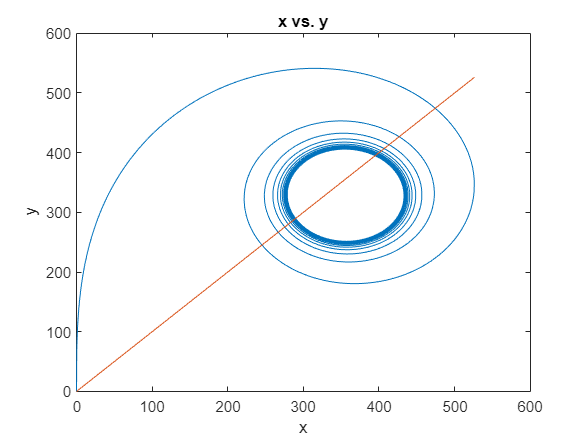

plot(x,y,x,x)
xlabel("x")
ylabel("y")
title("x vs. y")

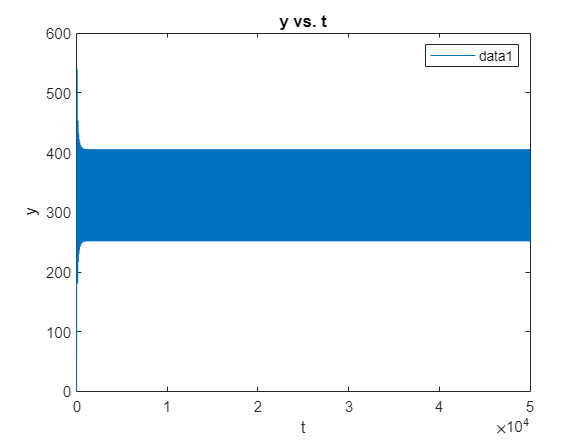

% Create plot of x and t
h3 = plot(t,y);

% Add xlabel, ylabel, title, and legend
xlabel("t")
ylabel("y")
title("y vs. t")
legend

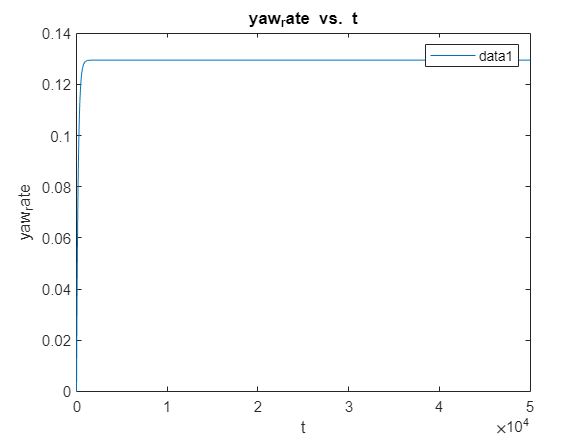

% Create plot of x and t
h3 = plot(t,r);

% Add xlabel, ylabel, title, and legend
xlabel("t")
ylabel("yaw_rate")
title("yaw_rate vs. t")
legend

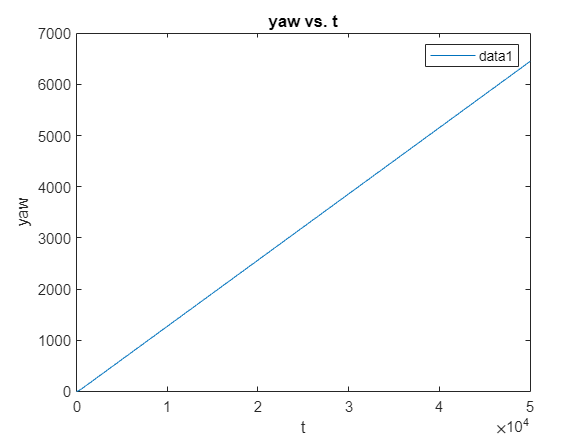

% Create plot of x and t
h3 = plot(t,psi);

% Add xlabel, ylabel, title, and legend
xlabel("t")
ylabel("yaw")
title("yaw vs. t")
legend